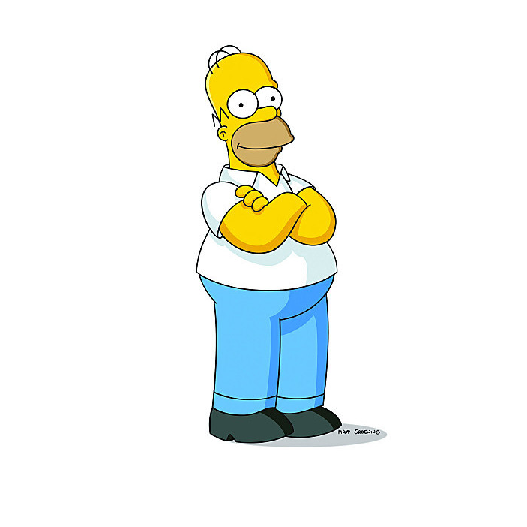

bild = imread("bild2.jpg");
%bild = imresize(bild, [300 300]);
figure;
imshow(bild);

figure;
zeile = size(bild,1);
b = mirrorEffect(bild, round(zeile/2));

   300

   599

   299

     1



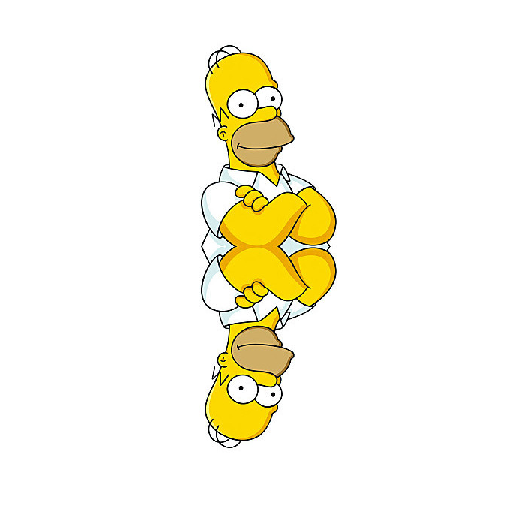

imshow(b)

figure;
zeile = size(bild,1);
br = mirrorEffectRotation(bild);

zeile = 299.5000

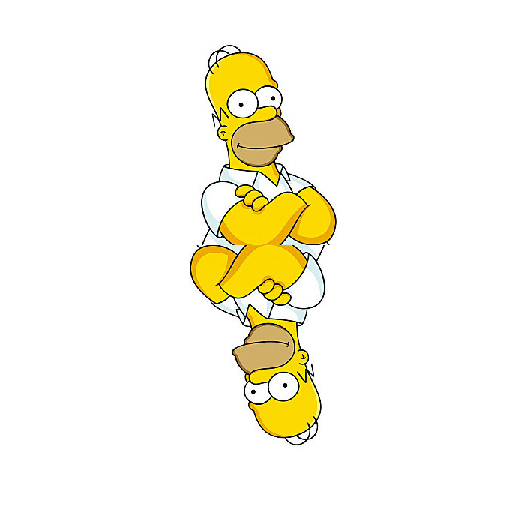

imshow(br);

figure;
spalte = size(bild,2);
b2 = mirrorEffect2(bild, round(spalte/2));

   261

   522

   261

     0



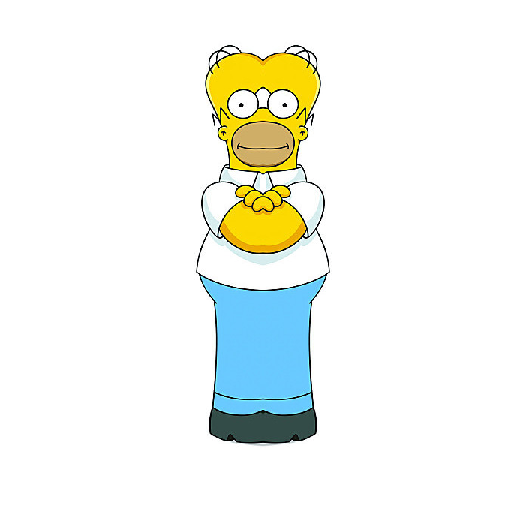

imshow(b2)

function mirrored = mirrorEffect(img,zeile)
    z = size(img,1);
    if (zeile >= z) || (zeile < z/2)
        error('Die gewählte Zeile ist ungültig!');
    end
    disp(zeile)
    disp(z)
    hoeheGespiegeltes = z-zeile;
    disp(hoeheGespiegeltes)
    disp(zeile-hoeheGespiegeltes)
    if zeile-hoeheGespiegeltes == 0
        hoeheGespiegeltes = hoeheGespiegeltes - 1; % so dass zeile-hoeheGespiegeltes = 1 ist
    end
    mirrored = [img(1:zeile-1,:,:); img(zeile:-1:zeile-hoeheGespiegeltes,:,:)];
end

function mirrored = mirrorEffectRotation(img)
    z = size(img,1);
    zeile = z / 2
    hoeheGespiegeltes = z-zeile;
    if zeile-hoeheGespiegeltes == 0
        hoeheGespiegeltes = hoeheGespiegeltes - 1; % so dass zeile-hoeheGespiegeltes = 1 ist
    end
    img2 = rot90(rot90(img(1:zeile-1,:,:)));
    mirrored = [img(1:zeile-1,:,:); img2];
end

function mirrored = mirrorEffect2(img, spalte)
    s = size(img, 2);
    if (spalte >= s) || (spalte < s/2)
        error('Die gewählte Spalte ist ungültig!');
    end
    disp(spalte)
    disp(s)
    breiteGespiegelt = s - spalte;
    disp(breiteGespiegelt)
    disp(spalte - breiteGespiegelt)
    if spalte-breiteGespiegelt == 0
        breiteGespiegelt = breiteGespiegelt - 1; % so dass zeile-hoeheGespiegeltes = 1 ist
    end
        mirrored = [img(:, 1:spalte-1,:), img(:, spalte:-1:spalte-breiteGespiegelt,:)];
    
end